Name    : Pranay Borgohain

Roll No. : 20EE01015

# **Digital Signal Processing Laboratory Experiment - 6**

% Defining some common functions to be used in this experiment

% making the value of heaviside() at origin equal to 1
sympref('HeavisideAtOrigin', 1);
u = @(n) heaviside(n);

% dirac delta function
delta = @(n) double(n == 0);

% defining the DTFT function
dtft = @(xn, n, w) xn * exp(-1j .* (n' * w));

% defining the DFT function
dft = @(xn, n) xn * exp((-1j * 2*pi/length(n)) .* (n' * (0:(length(n)-1))));

% defining range of frequencies (omega) from -pi to +pi
w = -pi:0.01:pi;

Q1:

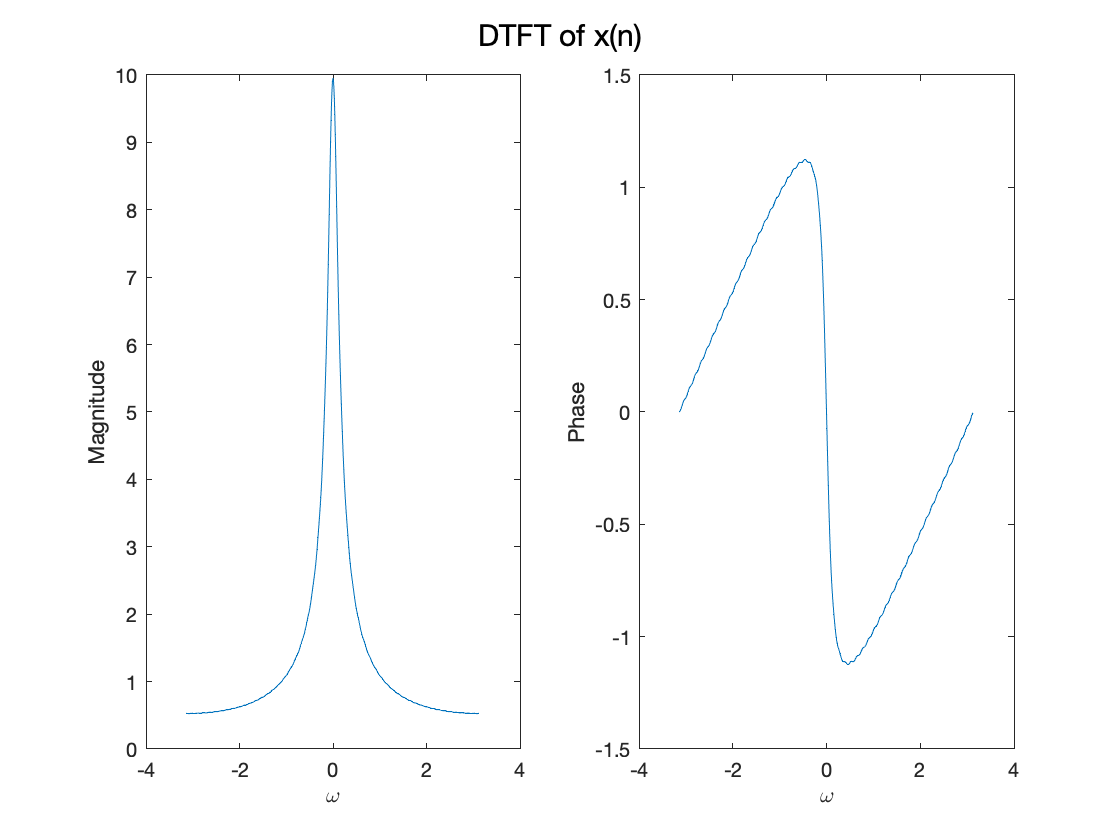

x = @(n) (0.9 .^ n) .* u(n);
n = 0:50;

xn = x(n);
[ym, m] = dnsample(xn, n, 2);

% (a)
X = dtft(xn, n, w);

figure;
subplot(1, 2, 1);
plot(w, abs(X));
xlabel("$\omega$", "Interpreter", "latex"); ylabel("Magnitude");
subplot(1, 2, 2);
plot(w, angle(X));
xlabel("$\omega$", "Interpreter", "latex"); ylabel("Phase");
sgtitle("DTFT of x(n)");

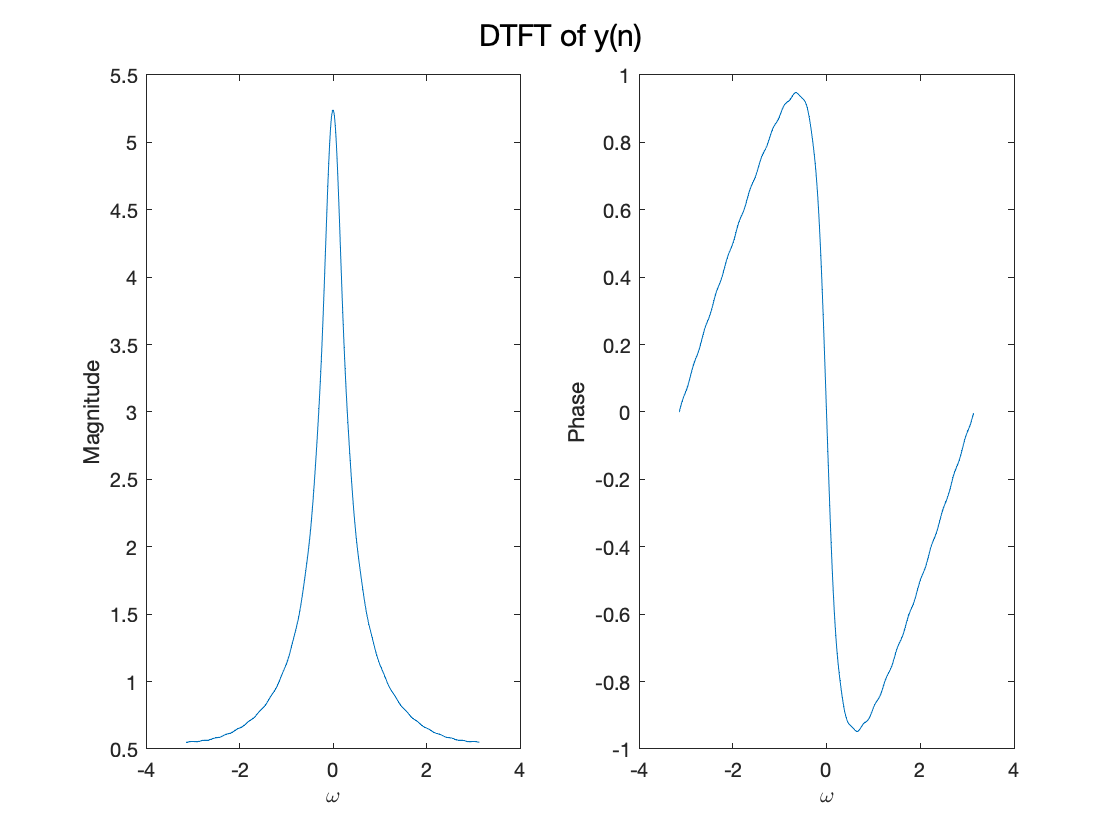

% (b)
Y = dtft(ym, m, w);

figure;
subplot(1, 2, 1);
plot(w, abs(Y));
xlabel("$\omega$", "Interpreter", "latex"); ylabel("Magnitude");
subplot(1, 2, 2);
plot(w, angle(Y));
xlabel("$\omega$", "Interpreter", "latex"); ylabel("Phase");
sgtitle("DTFT of y(n)");

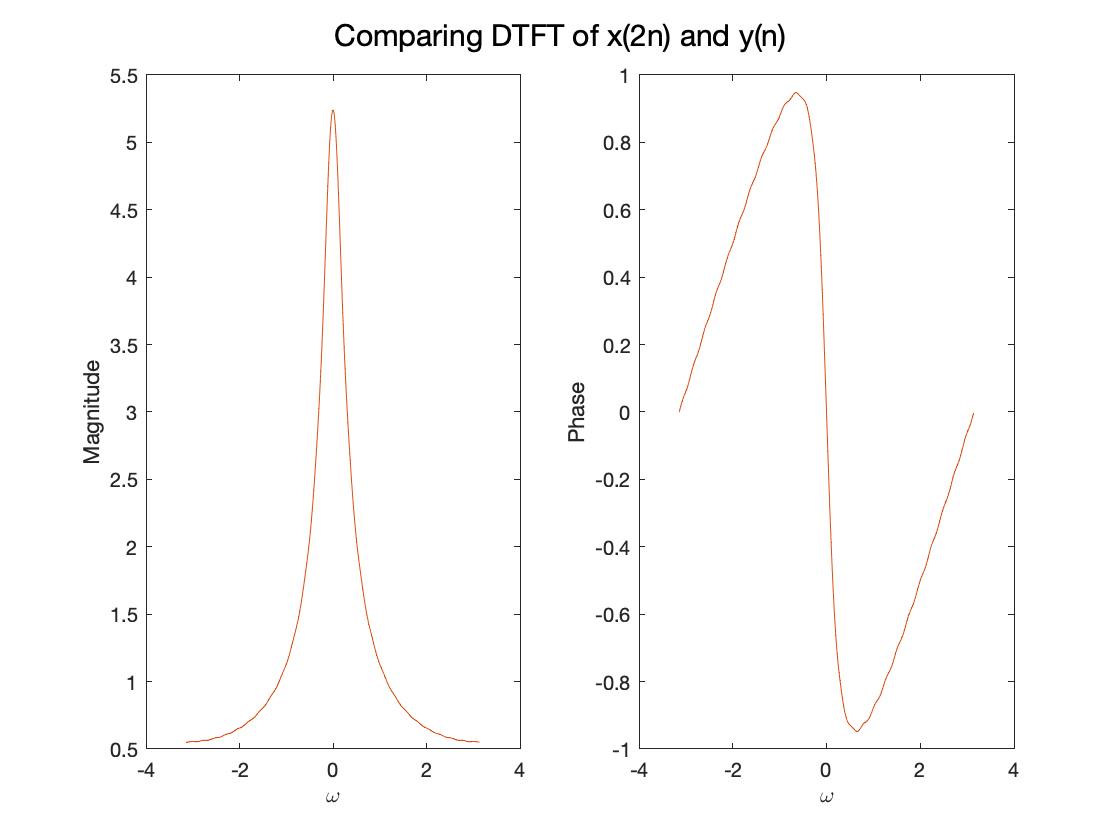

% (c)
x2n = xn(1:2:end);
X2 = dtft(x2n, n(1:2:end) ./ 2, w);

figure;
subplot(1, 2, 1);
plot(w, abs(X2));
hold("on");
plot(w, abs(Y));
xlabel("$\omega$", "Interpreter", "latex"); ylabel("Magnitude");

subplot(1, 2, 2);
plot(w, angle(X2));
hold("on");
plot(w, angle(Y));
xlabel("$\omega$", "Interpreter", "latex"); ylabel("Phase");
sgtitle("Comparing DTFT of x(2n) and y(n)");

We can see in the above figure that the two plots superimpose each other perfectly. Hence, it has been shown that the spectrum of $Y(\omega)$ is simply the DTFT of $x(2n)$.

Q2:

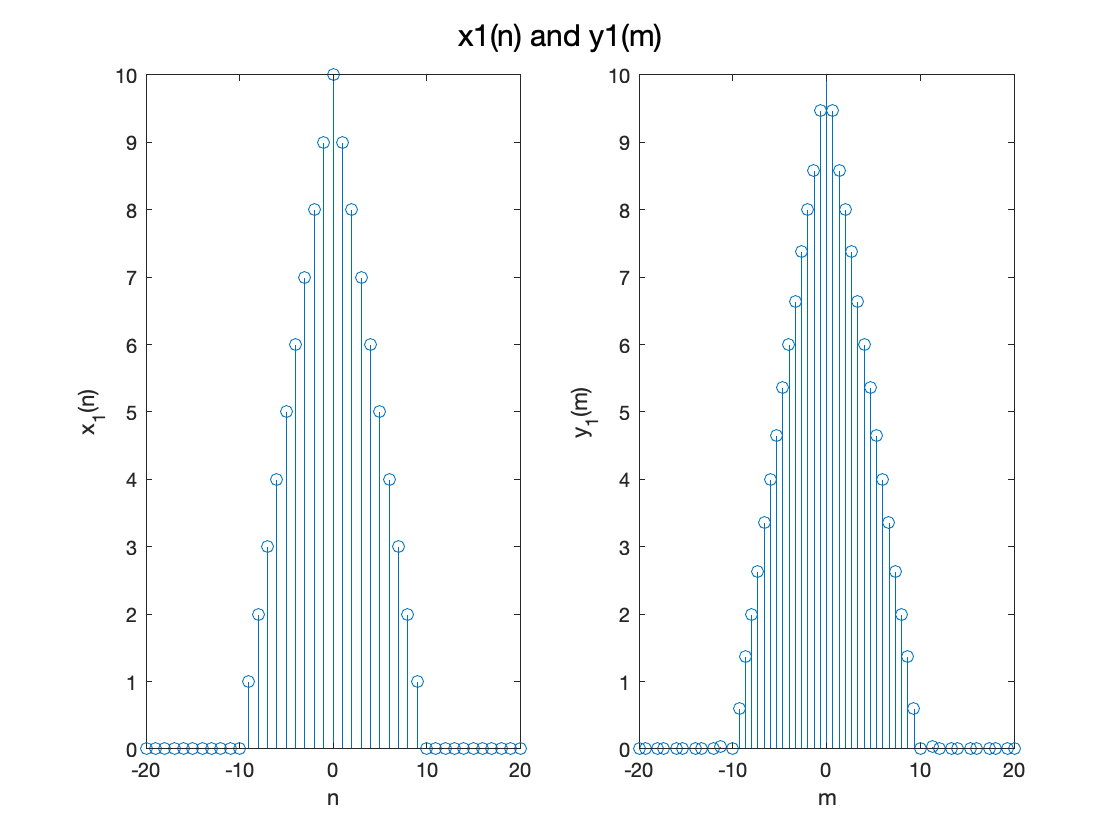

x1 = @(n) max(10 - abs(n), 0);
x2 = @(n) min(abs(n), 10);
n = -20:20;
m = -20:(2/3):20;

% (a)
x1n = x1(n);
y1m = resample(x1n, 3, 2);
y1m = y1m(1:length(m)); % making the size of y1m and m equal

figure;
subplot(1, 2, 1);
stem(n, x1n);
xlabel("n"); ylabel("x_{1}(n)");

subplot(1, 2, 2);
stem(m, y1m);
xlabel("m"); ylabel("y_{1}(m)");
axis([-20, 20, 0, 10]);
sgtitle("x1(n) and y1(m)");

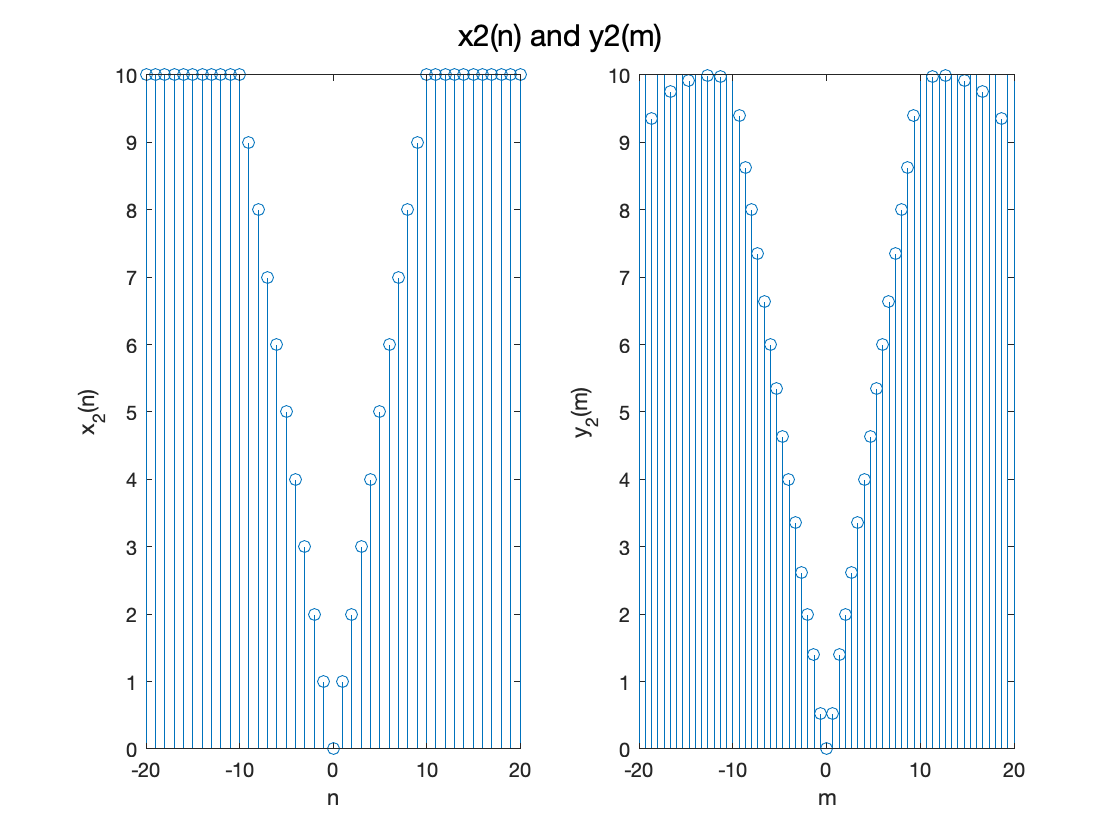

% (b)
x2n = x2(n);
y2m = resample(x2n, 3, 2);
y2m = y2m(1:length(m)); % making the size of y1m and m equal

figure;
subplot(1, 2, 1);
stem(n, x2n);
xlabel("n"); ylabel("x_{2}(n)");

subplot(1, 2, 2);
stem(m, y2m);
xlabel("m"); ylabel("y_{2}(m)");
axis([-20, 20, 0, 10]);
sgtitle("x2(n) and y2(m)");

c) In its filtering process, the $resample$ function assumes the samples at times before and after the given samples are equal to zero. Thus, large deviations from zero at the end points of the given sequence can cause inaccuracies in the end points of the output, as visible in the above plot. [referenced from the documentation for the $resample$ function using the **help resample** command]

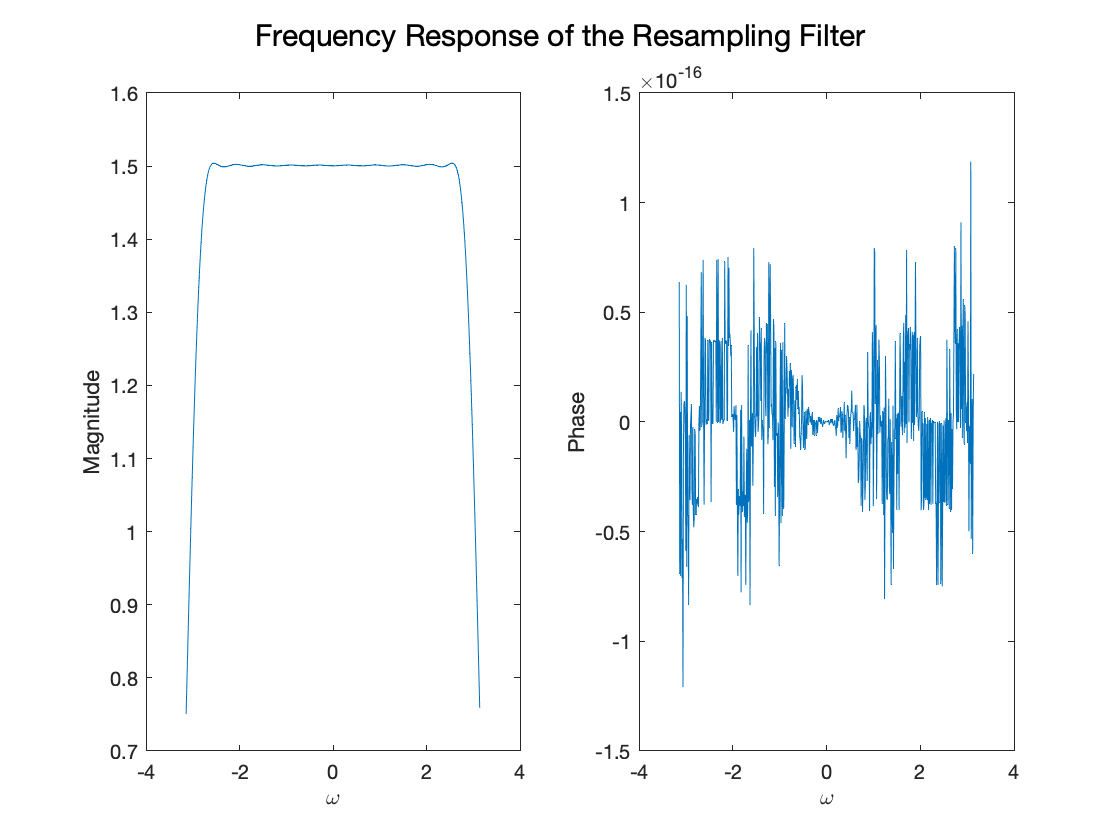

% (d)
n = -10:10;
m = -10:(2/3):10;

dirac_delta = delta(n);
hn = resample(dirac_delta, 3, 2);
% making the size of hn and m equal
hn = hn(1:length(m));

Hw = dtft(hn, m, w);

figure;
subplot(1, 2, 1);
plot(w, abs(Hw));
xlabel("$\omega$", "Interpreter", "latex"); ylabel("Magnitude");
subplot(1, 2, 2);
plot(w, angle(Hw));
xlabel("$\omega$", "Interpreter", "latex"); ylabel("Phase");
sgtitle("Frequency Response of the Resampling Filter");

Q3:

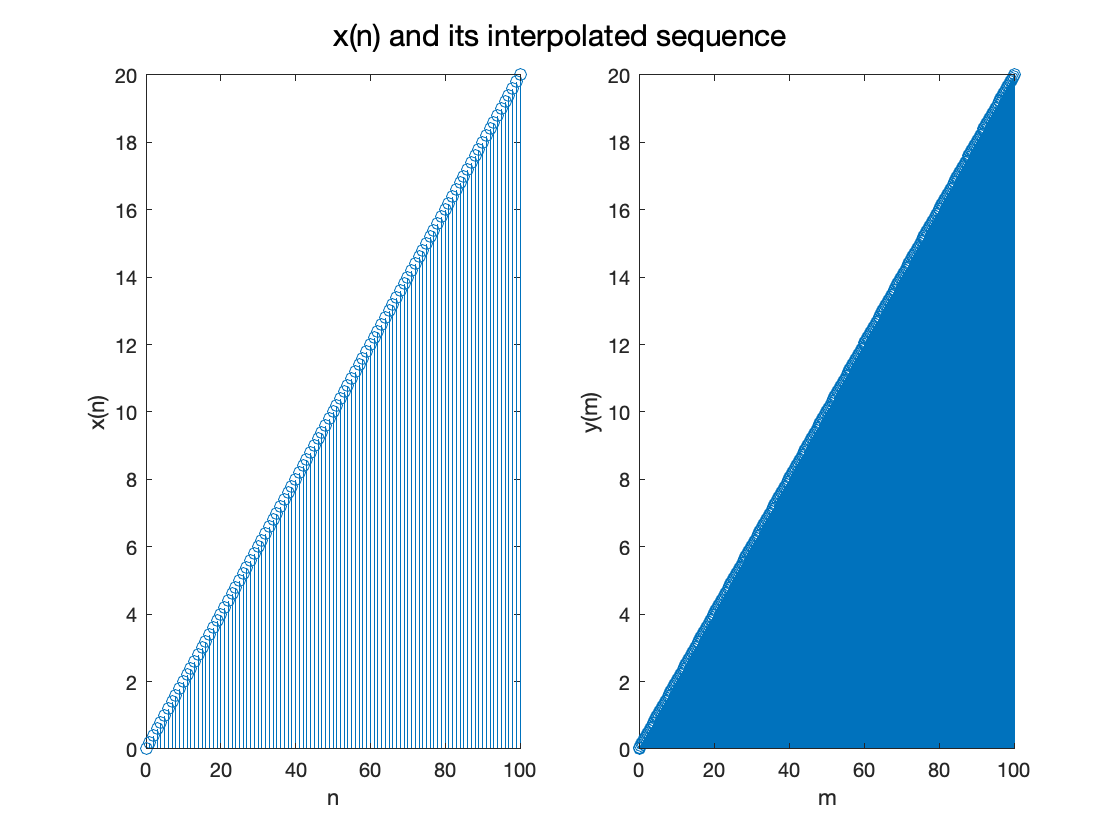

x = @(n) 0.2 .* n;
n = 0:100;
m = 0:(1/4):100;

xn = x(n);

% Interpolation
ym = interp(xn, 4);
ym = ym(1:length(m)); % making the size of ym and m equal

figure;
subplot(1, 2, 1);
stem(n, xn);
xlabel("n"); ylabel("x(n)");
subplot(1, 2, 2);
stem(m, ym);
xlabel("m"); ylabel("y(m)");
axis([0, 100, 0, 20]);
sgtitle("x(n) and its interpolated sequence");

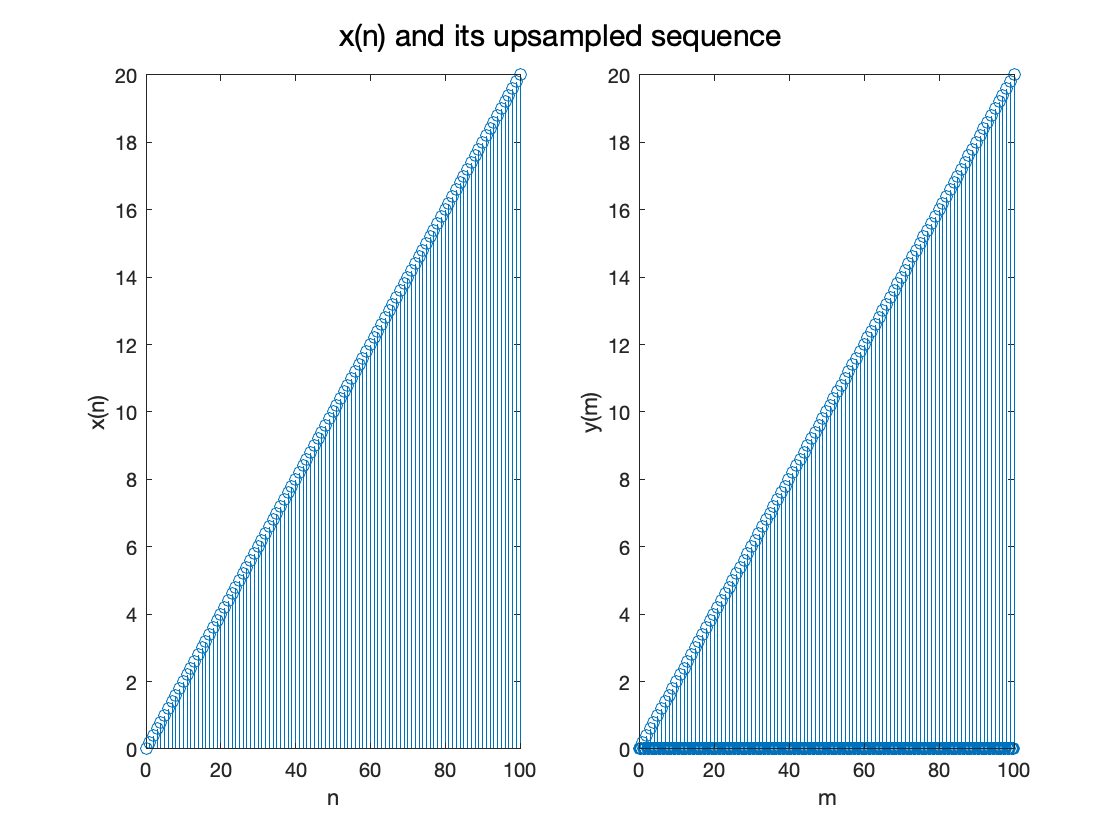

% Upsampling
ym = upsample(xn, 4);
ym = ym(1:length(m)); % making the size of ym and m equal

figure;
subplot(1, 2, 1);
stem(n, xn);
xlabel("n"); ylabel("x(n)");
subplot(1, 2, 2);
stem(m, ym);
xlabel("m"); ylabel("y(m)");
axis([0, 100, 0, 20]);
sgtitle("x(n) and its upsampled sequence");

Q4:

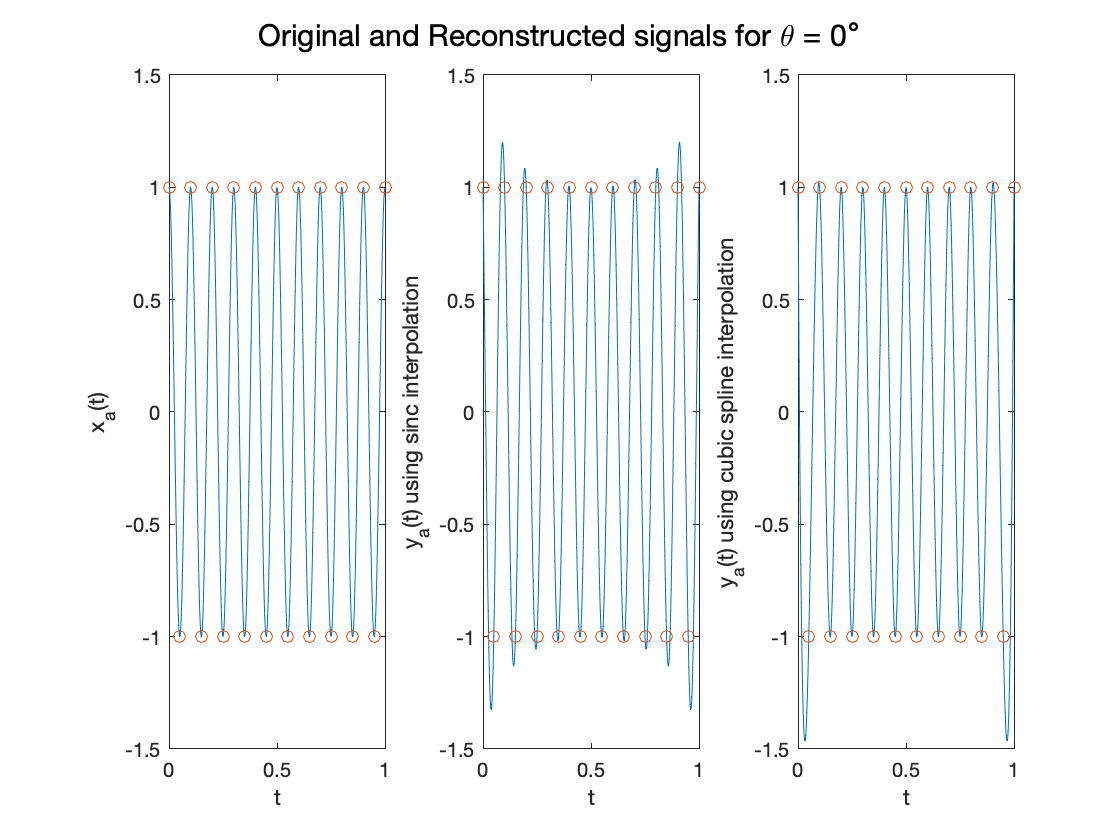

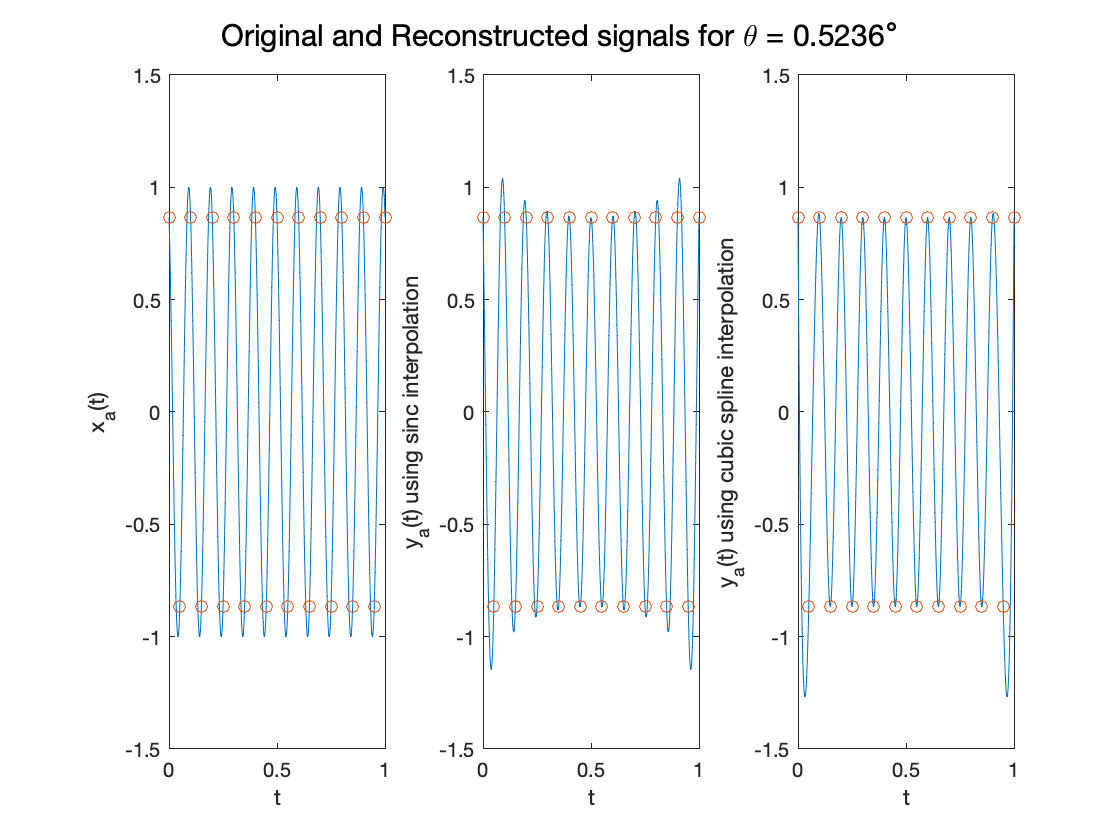

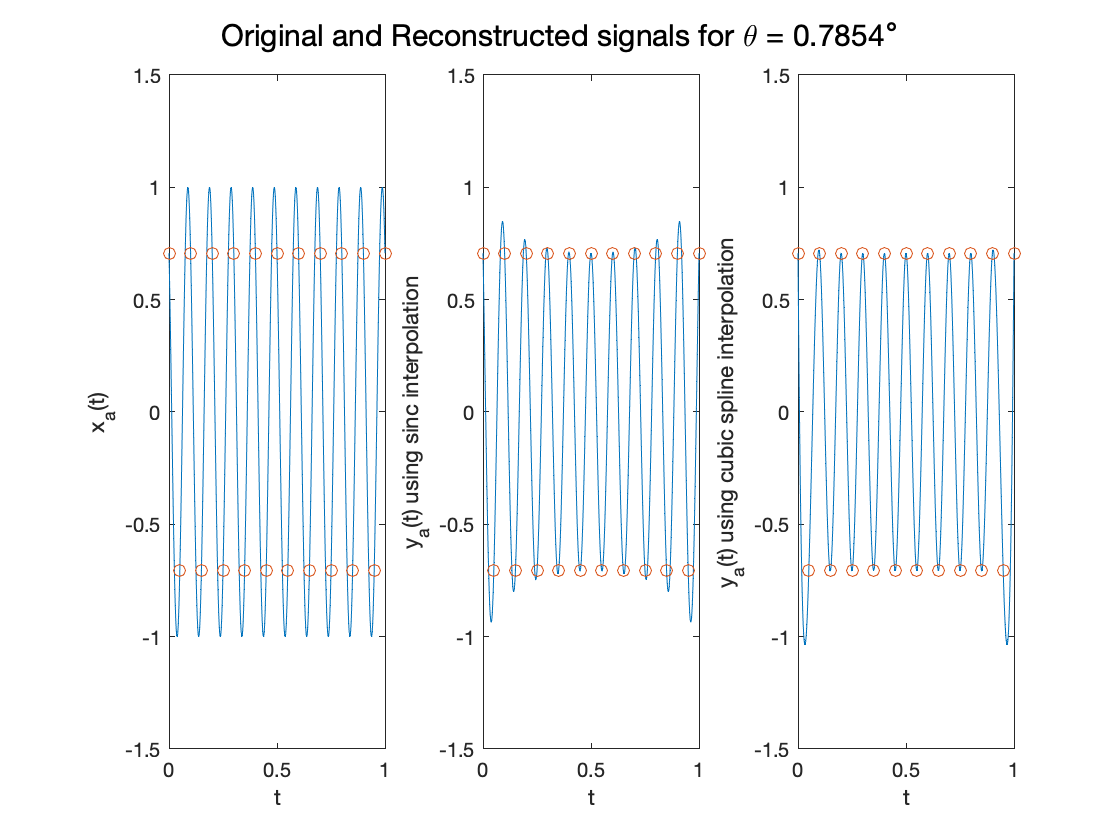

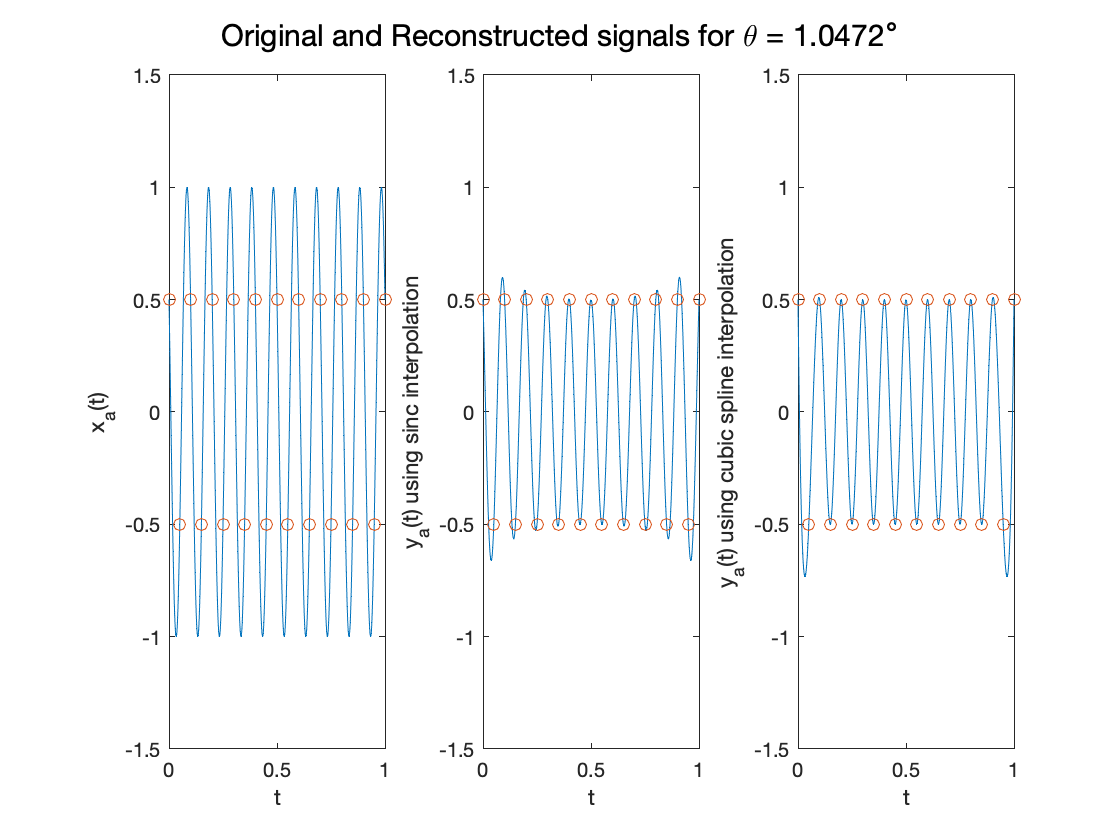

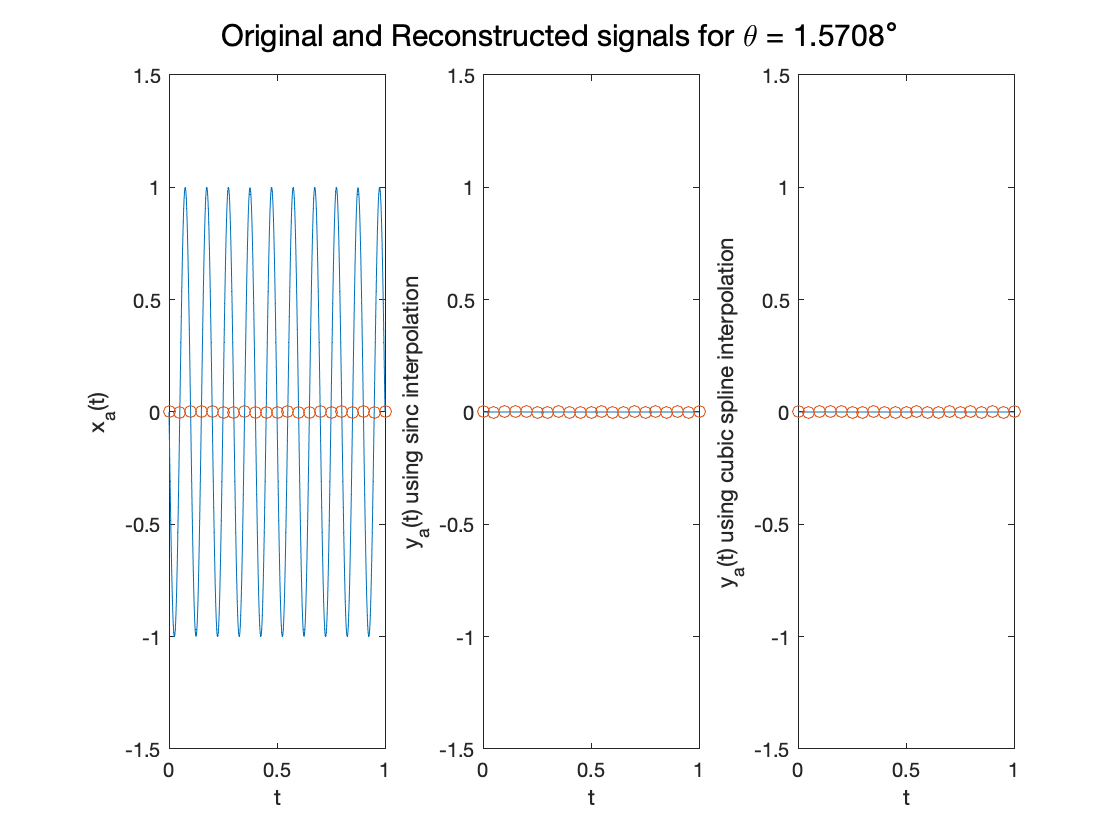

xa = @(t, theta) cos((20 .* pi .* t) + theta);

t = 0:0.001:1;
Ts = 0.05;
n = 0:Ts:1;

theta_array = [0, pi/6, pi/4 pi/3, pi/2];

for i = 1:length(theta_array)
    theta = theta_array(i);    
    xat = xa(t, theta);
    xn = xa(n, theta);

    figure;
    % (a)
    subplot(1, 3, 1);
    plot(t, xat, n, xn, 'o');
    xlabel("t"); ylabel("x_a(t)"); axis([0, 1, -1.5, 1.5]);

    % (b)
    yat_sinc = sinc_interp(xn, n, t, Ts);
    subplot(1, 3, 2);
    plot(t, yat_sinc, n, xn, 'o')
    xlabel("t"); ylabel("y_a(t) using sinc interpolation"); axis([0, 1, -1.5, 1.5]);
    
    % (c)
    yat_cubic_spline = spline(n, xn, t);
    subplot(1, 3, 3);
    plot(t, yat_cubic_spline, n, xn, 'o');
    xlabel("t"); ylabel("y_a(t) using cubic spline interpolation"); axis([0, 1, -1.5, 1.5]);
    
    sgtitle("Original and Reconstructed signals for \theta = " + theta + "\circ");
end

d) Overshoots and undershoots in cubic spline interpolation and filtering in sinc interpolation add information, and can cause a loss of amplitude in the reconstructed signal. Cubic spline interpolation can introduce phase distortion, which can alter the signal's shape and frequency content. Sinc interpolation can reconstruct a signal perfectly, but phase distortion can occur if the signal is not band-limited or the sampling rate is too low.

function [y, m] = dnsample(x, n, M)
    len = length(x);
    y = []; m = [];
    for i = 1:len
        if mod(n(i), M) == 0
           y = [y x(i)];
           m = [m n(i)/M];
        end
    end
end

function y = sinc_interp(x, n, t, T)
    t_matrix = ones(length(n), 1) * t;
    n_matrix = n' * ones(1, length(t));
    
    sinc_matrix = sinc((t_matrix - n_matrix) ./ T);
    
    y = x * sinc_matrix;
end